Problem 1)

h5disp("gammaray_lab4.h5")

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


data = h5read("gammaray_lab4.h5",'/data')

data = 	1.0e+08 *

    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000
    9.4068    0.0000    0.0000    0.0000


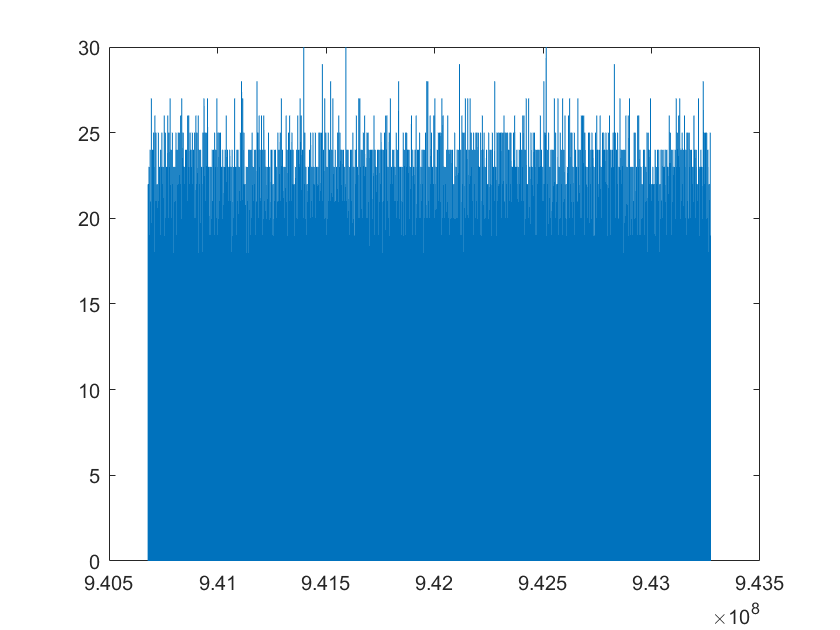

plot(data(:,1),data(:,4),"Linewidth",0.1)

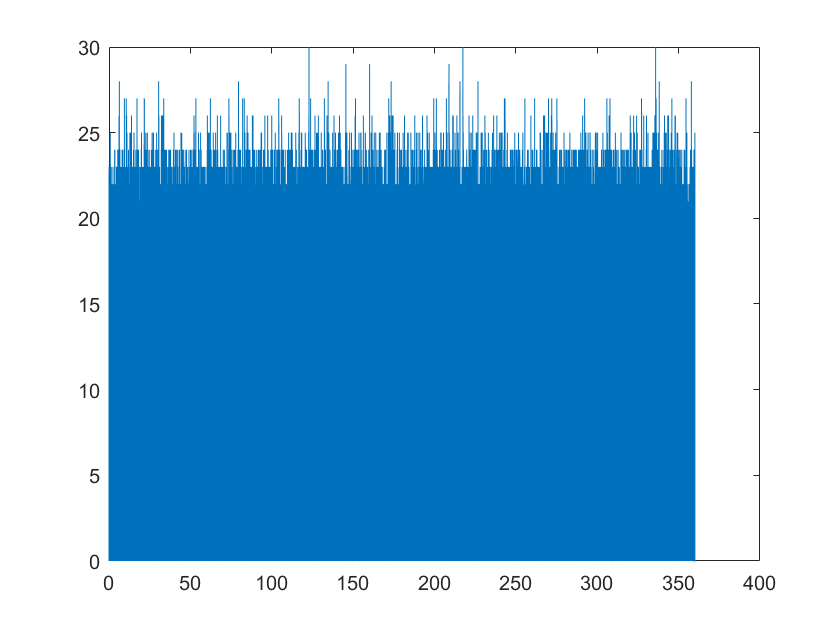

plot(data(:,2),data(:,4),"Linewidth",0.1)

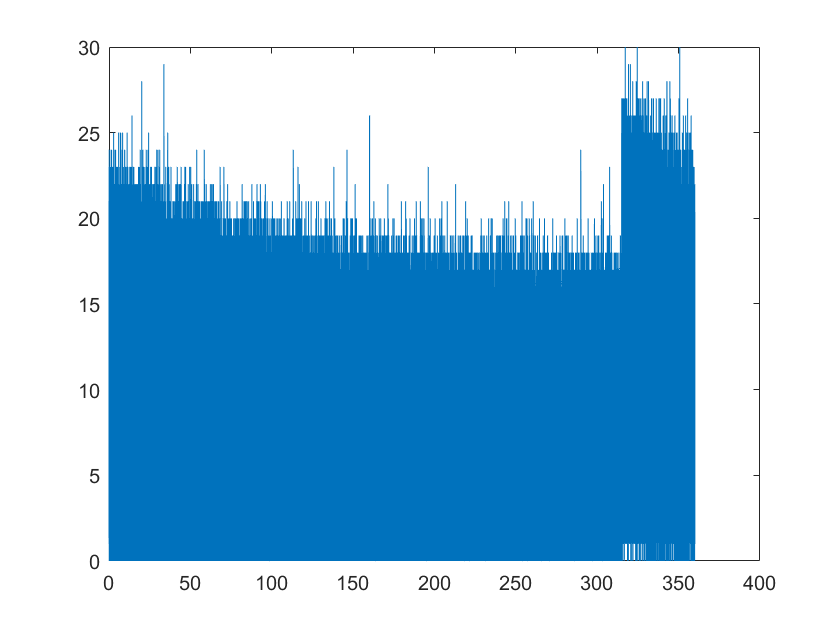

plot(data(:,3),data(:,4),"Linewidth",0.1)

Here we've loaded the data and made plots of gps time, solar degrees and degrees of latitude vs counts. Initially everything looks messy, but we have a lot of data. We take data every .1 seconds, and we have a 90 minute orbit around the Earth. Below we'll plot an interval of 100000 data points, corresponding to intervals of roughly two orbits, of gps time against solar and latitutde degrees to confirm 54000 data points corresponds to two orbits. 

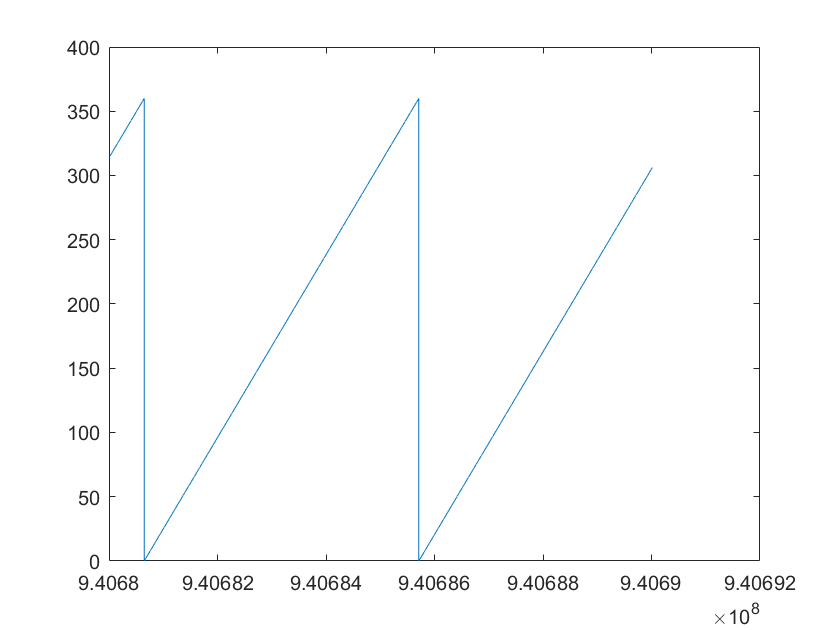

plot(data(1:100000,1),data(1:100000,2),"Linewidth",0.1)

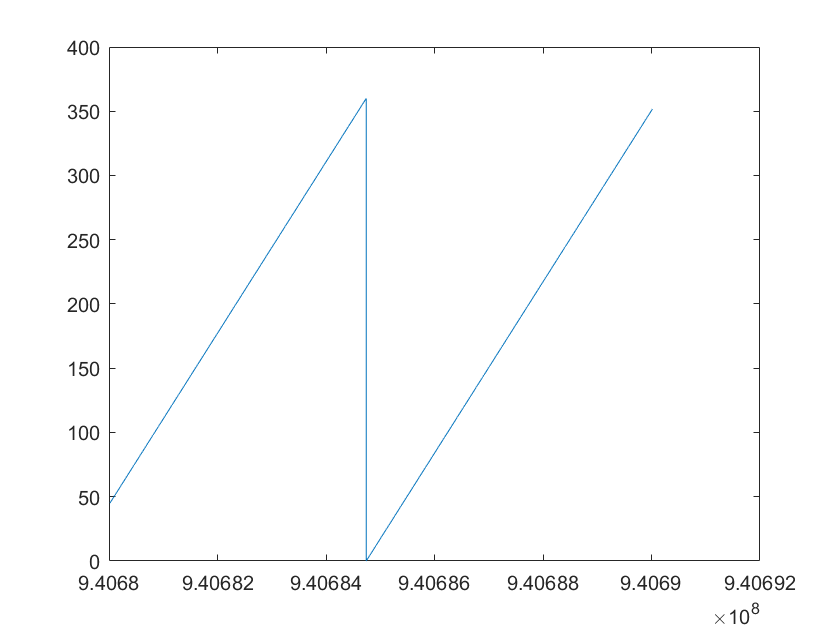

plot(data(1:100000,1),data(1:100000,3),"Linewidth",0.1)

Here we can see that 100000 data points is roughly two solar cycles, and a little less than two orbits which is expected for less than 2*54000 data points, where 54000 data points is one orbit. Taking one orbit as 54000, data points, assuming every orbit is offset from a solar degree cycle by 90 minutes, one solar cycle should be 54000 data points * 22.5hrs/24hrs = 50625, confirming that we are looking at roughly two solar cycles. 

Now lets see if our counts are more affected by the periods of the sun or the Earth around our satellite. 

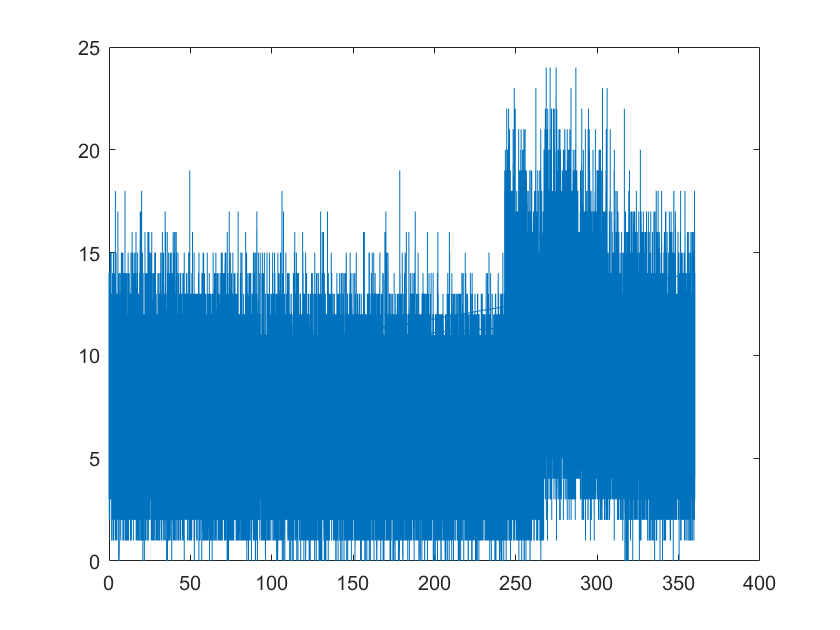

plot(data(1:100000,2),data(1:100000,4),"Linewidth",0.1)

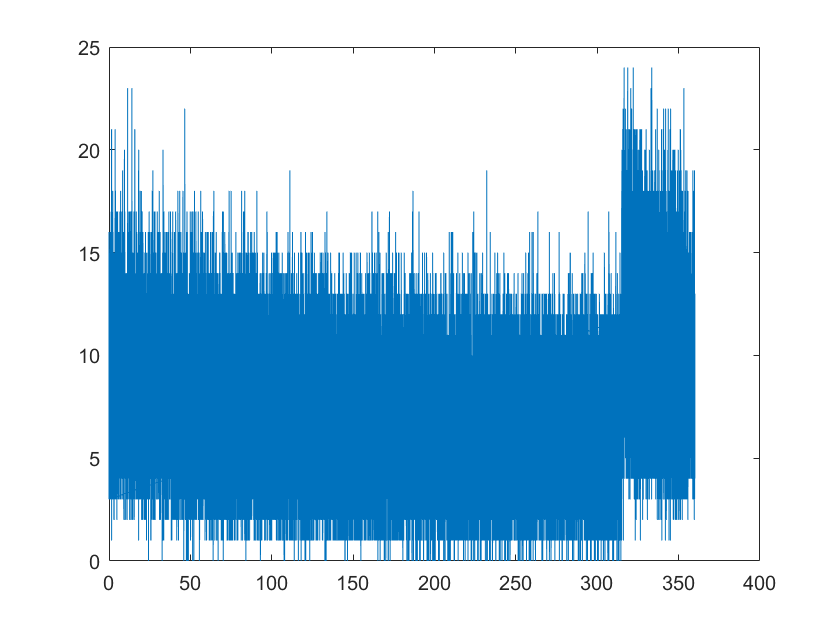

plot(data(1:100000,3),data(1:100000,4),"Linewidth",0.1)

Below we'll plot a histogram of the data from one total day - and voila, a Poisson distribution. We can take these from different times of day and use them as pdf's for different times of day 

dhist = data(1:54000,4)

dhist =     10
     8
     7
    11
     8
    11
     5
    10
     9
     8


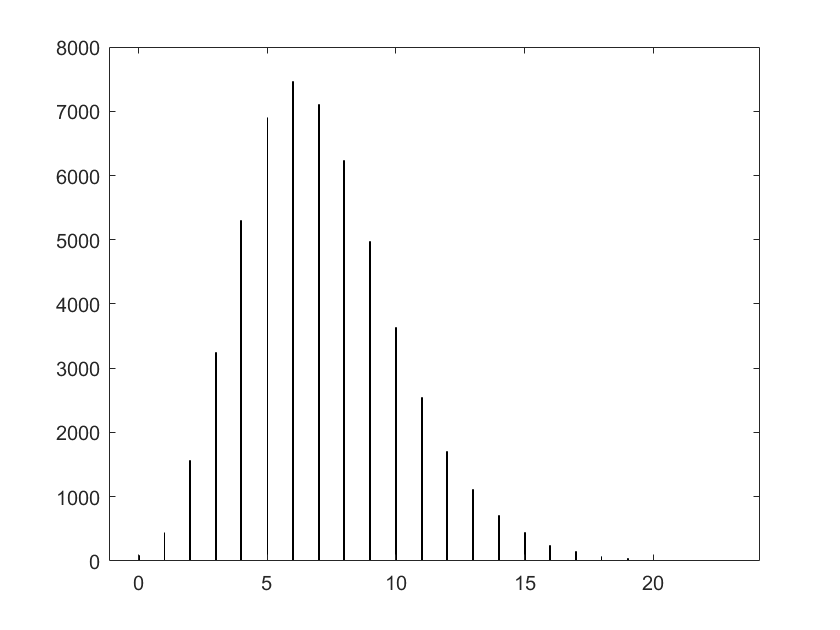

hist =   Histogram with properties:

             Data: [54000×1 double]
           Values: [1×1000 double]
          NumBins: 1000
         BinEdges: [1×1001 double]
         BinWidth: 0.0230
        BinLimits: [0 23]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


hist = histogram(dhist,1000)